clc;

n = -10:10;
u = (n>=0);

r = n.*u;

a = 0.8;
e = (a.^n).*(n>=0);

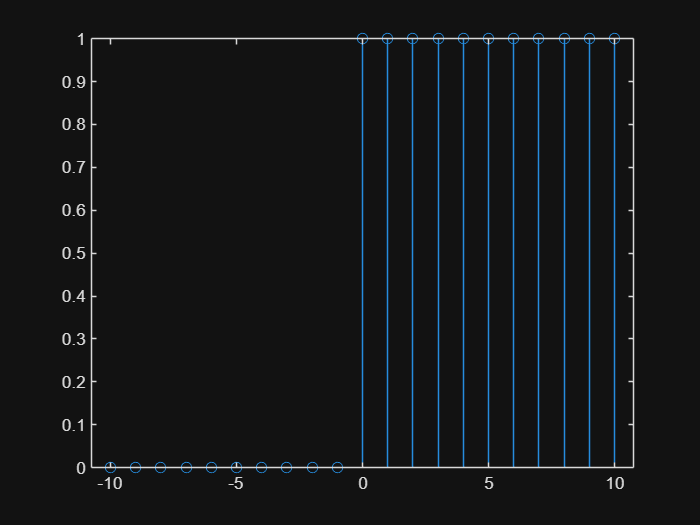

stem(n, u);

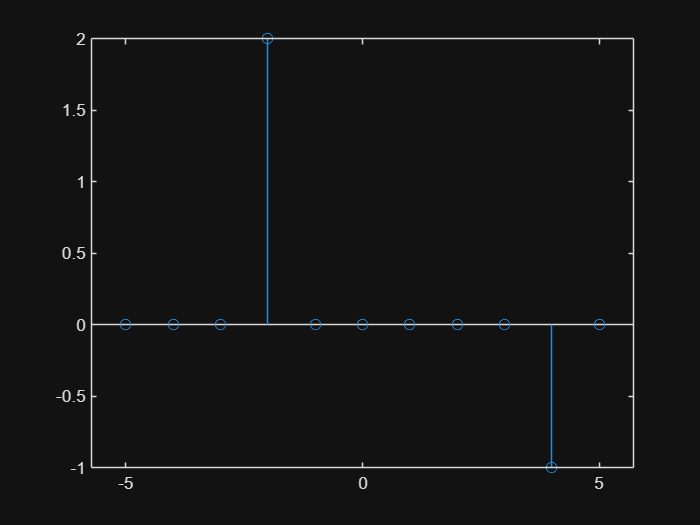

n = -5: 5;
x = 2*(n==-2) - (n==4);

stem(n, x);

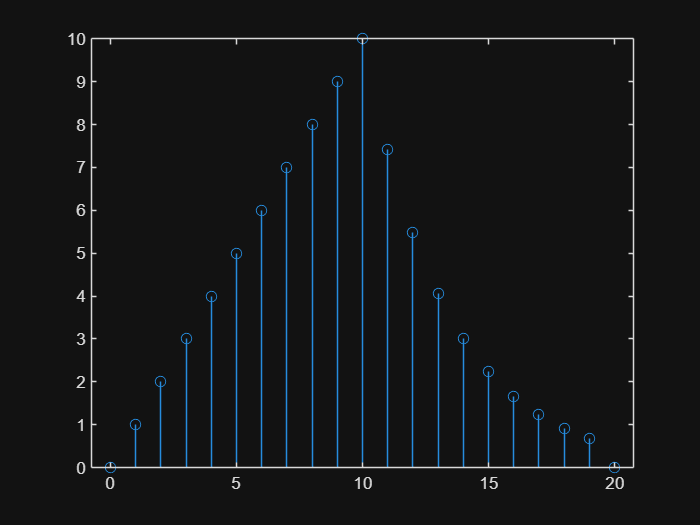

n = 0:20;
u = @(n) n >= 0;

x = n.*(u(n) - u(n-10)) + 10*exp(-0.3*(n-10)).*(u(n-10) - u(n-20));

stem(n, x);

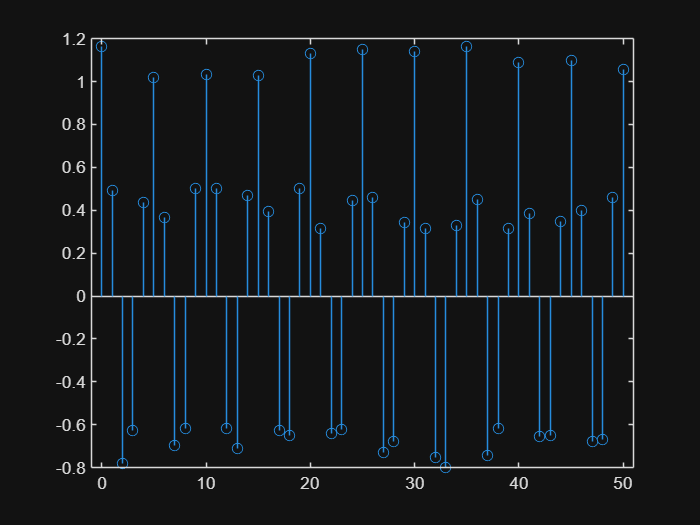

n = 0:50;
w = rand(size(n));
x = cos(0.4*pi*n) + 0.2* w;

stem(n, x);

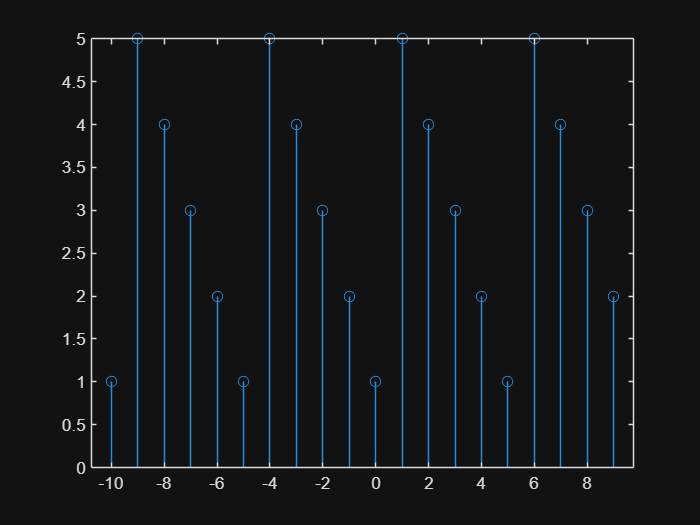

n = -10:9;
x = mod(-n, 5) + 1;

stem(n, x);

n = -10:10;
x = exp(0.1 + 0.3*1j)*n

x =  -10.5581 - 3.2660i  -9.5023 - 2.9394i  -8.4465 - 2.6128i  -7.3907 - 2.2862i  -6.3349 - 1.9596i  -5.2791 - 1.6330i  -4.2232 - 1.3064i  -3.1674 - 0.9798i  -2.1116 - 0.6532i  -1.0558 - 0.3266i   0.0000 + 0.0000i   1.0558 + 0.3266i   2.1116 + 0.6532i   3.1674 + 0.9798i   4.2232 + 1.3064i   5.2791 + 1.6330i   6.3349 + 1.9596i   7.3907 + 2.2862i   8.4465 + 2.6128i   9.5023 + 2.9394i  10.5581 + 3.2660i


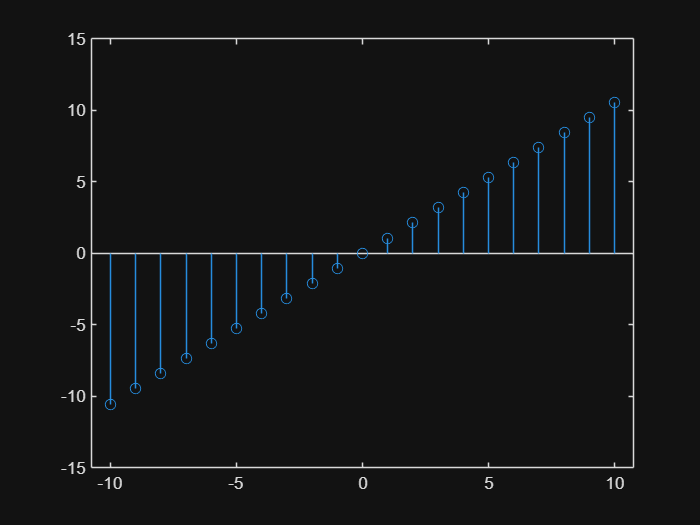


stem(n, real(x));

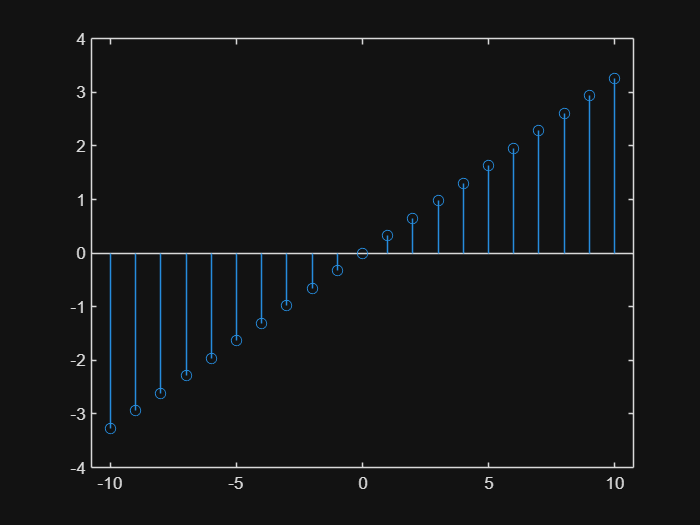

stem(n, imag(x))

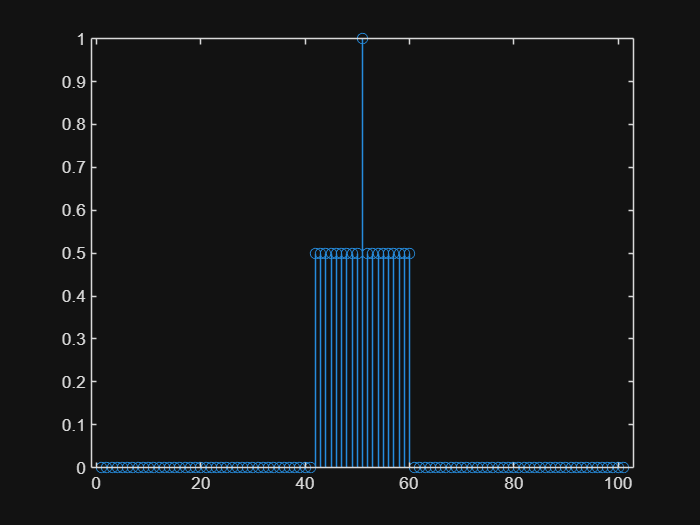

n = -50:50;

x = u(n) - u(n-10);
x_neg = fliplr(x);

xo = (x-x_neg) /2;
xe = (x + x_neg) /2;

stem(xe);

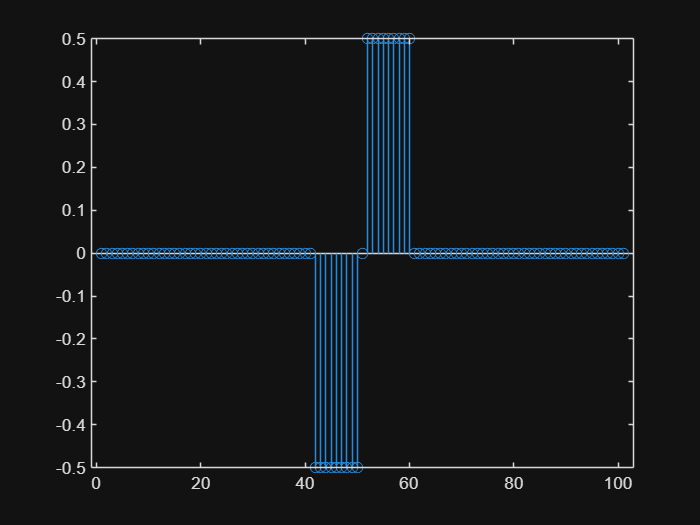

stem(xo);

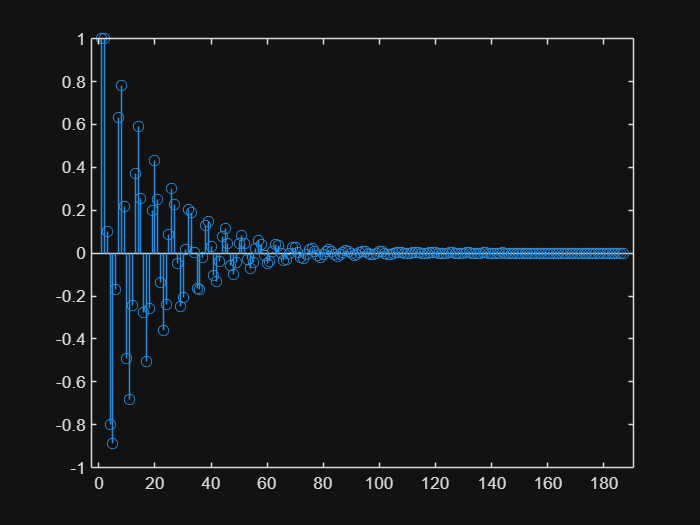

n = -20 : 100;
b = [1];
a = [1 -1 0.9];

h  = impz(b, a);
stem(h);

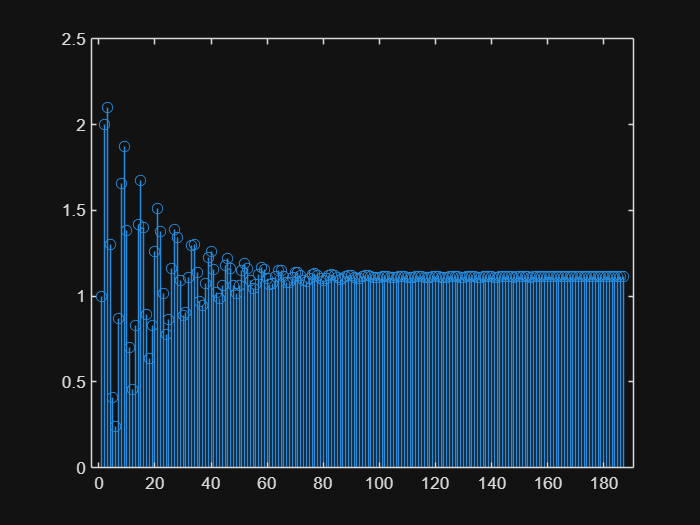


s = stepz(b, a);
stem(s);

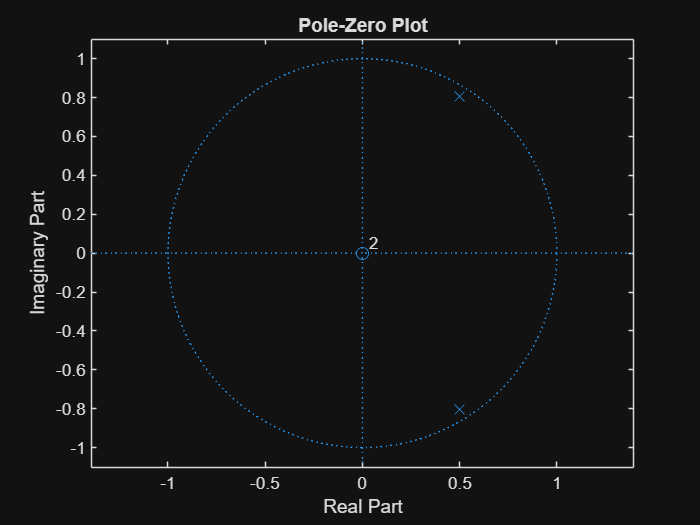



z = zplane(b, a);

stem(z);

Error using assert
Not enough input arguments.

Error in stem (line 78)
    assert(numel(args) >= 1, message('MATLAB:narginchk:notEnoughInputs'));
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

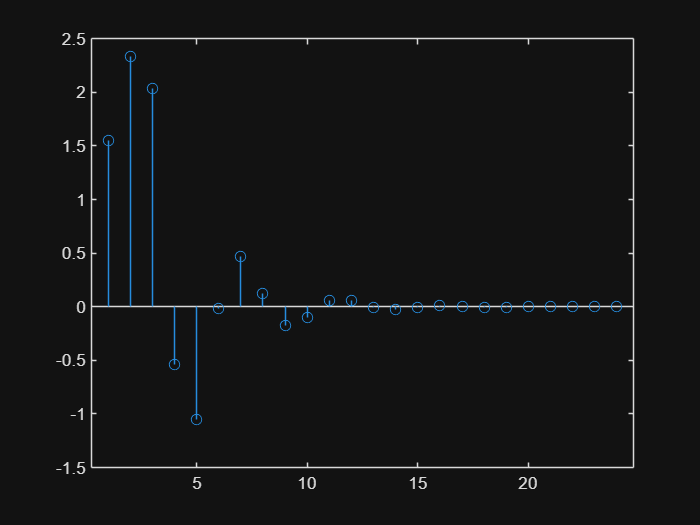

 b = [1.55 1.95 2.15];
 a = [1 -.25 0.45];

 h = impz(b, a);
 stem(h);

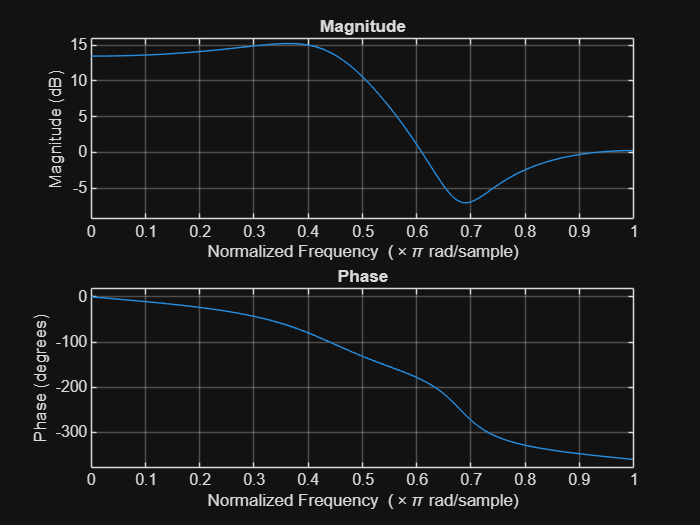


 freqz(h);

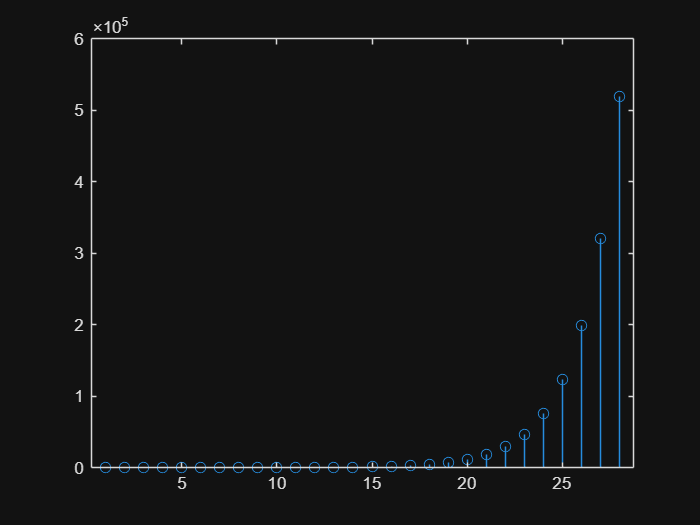

b = [1 0.5 0.85];
a = [1 -1 -1];

h = impz(b, a);
stem(h);